# Extracting signal data and filtering


clear all

home_dir = 'D:/experiment_pics/';

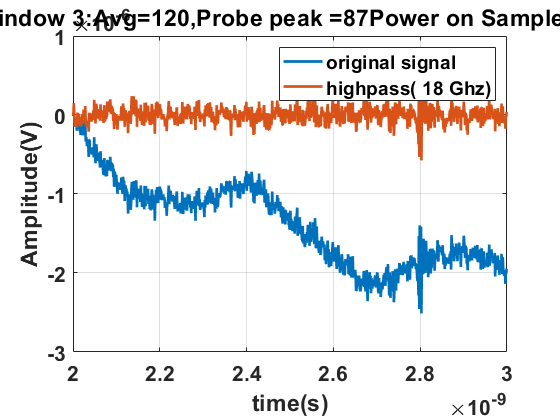

% Function instructions 
% [data,data_filt, echo_location,error] = extract_first_echo_selected_phase...
% (home_dir,date,name,del_t,time_window_size,plotflag,N_avg,Probe_power,Sample_power,phase_selection,win) 
norm = 0;
plotflag = 1;
win = 3;
date = '08_2022/02_08_22';
del_t = 0.5985e-9;
time_window_size = 0.3e-9/2;
count = 5;
i = 7;
fzp_sig = [];
no_fzp_sig = [];
%count = 0;
switch date 
    case '08_2022/02_08_22'
    name1 = 'tip_newpd_probepk87_poweronsample2p9_Navg120_Nwin1_win3_align3';
    N_avg1 = 120;
    Probe_peak = 87;
    Sample_power = 3;
    phase_selection=1;
    time_window_size= [2.75e-9,2.85e-9]; 
    [tip_newpd_s3_3,tip_newpd_s3_3_filt,~,err_avg120_1] = ...
        extract_first_echo_selected_phase(home_dir,date,name1,del_t,time_window_size,plotflag,N_avg1,Probe_peak,Sample_power,phase_selection,win);
    
    case '07_2022/13_07_22' 
    thermaldecay_name_newconfig_pd2_s6_366mV_10win = 'thermaldeacay_newpd_peak366mVpower3p12mW_Navg40_1win';
    N_avg = 40;
    Probe_peak = 366;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [thermdecay_noFZP_s6_newconfigpd2_366mV,thermdecay_noFZP_s6_newconfigpd2_366mV_filt,~,err_avg40_p3120_pd2] = ...
        extract_first_echo(home_dir,date,thermaldecay_name_newconfig_pd2_s6_366mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=3120\muW,',phase_selection);
    
    thermaldecay_pumpoff_name_newconfig_pd2_s6_366mV_10win = 'thermaldeacay_pumpoff_newpd_peak366mVpower3p12mW_Navg40_1win';
    N_avg = 40;
    Probe_peak = 366;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [thermdecay_pumpoff_noFZP_s6_newconfigpd2_366mV,~,~,err_avg40_p3120_pd2_pumpoff] = ...
        extract_first_echo(home_dir,date,thermaldecay_pumpoff_name_newconfig_pd2_s6_366mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=3120\muW,',phase_selection);
    
    case '07_2022/12_07_22' 
    name_newconfig_pd2_s6_366mV_10win = 'newpd_peak366mVpower3p12mW_Navg60_10win';
    N_avg = 60;
    Probe_peak = 366;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multecho_noFZP_s6_newconfigpd2_366mV,multecho_noFZP_s6_newconfigpd2_filt_366mV,~,err_avg60_p3120_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_366mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=3120\muW,',phase_selection);
    
    case '07_2022/11_07_22' 
    name_newconfig_pd2_s6_88mV_10win = 'newpd_peak88mVpower0p740mW_Navg60_10win';
    N_avg = 60;
    Probe_peak = 88;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multecho_noFZP_s6_newconfigpd2_88mV,multecho_noFZP_s6_newconfigpd2_filt_88mV,~,err_avg60_p740_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_88mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=740\muW,',phase_selection);    
    
    name_newconfig_pd2_s6_343mV_10win = 'newpd_peak343mVpower3p11mW_Navg120_10win';
    N_avg = 120;
    Probe_peak = 343;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multecho_noFZP_s6_newconfigpd2_343mV,multecho_noFZP_s6_newconfigpd2_filt_343mV,~,err_avg120_p3120_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_343mV_10win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=3120\muW,',phase_selection);
        
    name_newconfig_pd2_s6_184mV_1win = 'newpd_peak184p3power1p65mW_Navg60_1win';
    N_avg = 60;
    Probe_peak = 184;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [echo_noFZP_s2_newconfigpd2_184mV,echo_noFZP_s2_newconfigpd2_filt_184mV,~,err_avg60_p1650_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_184mV_1win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=1650\muW,',phase_selection);
        
    name_newconfig_pd2_s6_96mV_5win = 'newpd_peak96_Navg60_5win';
    N_avg = 60;
    Probe_peak = 96;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multechos_noFZP_s2_newconfigpd2_96mV,multechos_noFZP_s2_newconfigpd2_filt_96mV,~,err_avg60_p800_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_96mV_5win,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=800\muW,',phase_selection);
        
    name_newconfig_pd2_s6_96mV = 'newpd_peak96_Navg60_1win';
    N_avg = 60;
    Probe_peak = 96;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [echo_noFZP_s2_newconfigpd2_96mV,echo_noFZP_s2_newconfigpd2_filt_96mV,~,err_avg60_p750_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_96mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=800\muW,',phase_selection);
    
    case '07_2022/08_07_22'     
    name_newconfig_pd2_s6_66mV = 'newpd_peak66_Navg60_5win';
    N_avg = 60;
    Probe_peak = 66;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multechos_noFZP_s2_newconfigpd2_66mV,multechos_noFZP_s2_newconfigpd2_filt_66mV,~,err_avg60_p550_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_66mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=550\muW,',phase_selection);
    
    name_newconfig_pd2_s6_88mV = 'newpd_peak88_Navg50_4win';
    N_avg = 50;
    Probe_peak = 88;
    del_t = 0.659e-9;
    time_window_size = 0.3e-9/2;
    phase_selection =0;
    [multechos_noFZP_s2_newconfigpd2_88mV,multechos_noFZP_s2_newconfigpd2_filt_88mV,~,err_avg60_p740_pd2] = ...
        extract_first_echo(home_dir,date,name_newconfig_pd2_s6_88mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'power=740\muW,',phase_selection);
    
     case '06_2022/20_06_22'     
    name_nofzp_new_config_s5_250mV = 'nofzp_s5_250mV_51p4muW_20avg_1win';
    N_avg = 20;
    Probe_peak = 250;
    phase_selection =0;
    [nofzp_new_config_s5_250mV,nofzp_new_config_s5_250mV_filt,~,err_avg20_p51p4] = ...
        extract_first_echo(home_dir,date,name_nofzp_new_config_s5_250mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'old',phase_selection);
    
    name_nofzp_new_config_s5_450mV = 'nofzp_s5_450mV_80muW_20avg_1win';
    N_avg = 20;
    Probe_peak = 976;
    phase_selection =0;
    [nofzp_new_config_s5_450mV,nofzp_new_config_s5_450mV_filt,~,err_avg20_p80] = ...
        extract_first_echo(home_dir,date,name_nofzp_new_config_s5_450mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'old',phase_selection);
    
    case '06_2022/17_06_22'     
    name_nofzp_new_config_s5_606mV = 'nofzp_s5_606mVsat_20avg_1win';
    N_avg = 20;
    Probe_peak = 606;
    phase_selection =0;
    [nofzp_new_config_s5_606mV,nofzp_new_config_s5_606mV_filt,~,err_avg20_p107] = ...
        extract_first_echo(home_dir,date,name_nofzp_new_config_s5_606mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'old',phase_selection);
    
    name_nofzp_new_config_s5_976mV = 'nofzp_s5_976mVsat_20avg_1win';
    N_avg = 20;
    Probe_peak = 976;
    phase_selection =0;
    [nofzp_new_config_s5_976mV,nofzp_new_config_s5_976mV_filt,~,err_avg60_p243] = ...
        extract_first_echo(home_dir,date,name_nofzp_new_config_s5_976mV,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'old',phase_selection);
    
    case '06_2022/15_06_22'     
    name_pump_fzp_new_config = 'fzp_oldconfig_multbody_572mV_60avg_5win';
    N_avg = 60;
    Probe_peak = 572;
    phase_selection =0;
    [multechos_noFZP_s2_newconfig,multechos_noFZP_s2_newconfig_filt,~,err_avg60_1] = ...
        extract_first_echo(home_dir,date,name_pump_fzp_new_config,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'old',phase_selection);
    
    name_pump_fzp_old_config = 'fzp_tipang_3y1x_pump_offset_530mV_240avg_1win3';
    N_avg = 240;
    Probe_peak = 530;
    phase_selection =1;
    [FZP_s2_3y1xold,FZP_s2_3y1xold_filt,~,err_avg240_1] = ...
        extract_first_echo(home_dir,date,name_pump_fzp_old_config,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'old',phase_selection);
    
    
    case '06_2022/14_06_22'     
    name_pump_fzp_1y19x = 'fzp_tip2_1y19x_multechoes_body_582mV_60avg_4win';
    N_avg = 60;
    Probe_peak = 582;
    phase_selection =0;
    [multechos_FZP_s2_1y19x,multechos_FZP_s2_1y19x_filt,~,err_avg60_2] = ...
        extract_first_echo(home_dir,date,name_pump_fzp_1y19x,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'1y19x',phase_selection);
        
    name_pump_fzp_1y18x = 'fzp_tip2_1y18x_sympump_align_497mV_400avg_4win3';
    N_avg = 400;
    Probe_peak = 497;
    phase_selection =1;
    [full_FZP_s2_1y18x,full_FZP_s2_1y18x_filt,~,err_avg400_1] = ...
        extract_first_echo(home_dir,date,name_pump_fzp_1y18x,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'1y18x',phase_selection);
    

    
    
    case '06_2022/13_06_22'        
    name_pump_fzp_1y17x = 'fzp_tip2_1y16x_sympump_align_500mV_500avg_4win';
    N_avg = 600;
    Probe_peak = 500;
    [full_FZP_s2_pump_off_1y17x,full_FZP_s2_pump_off_1y17x_filt,~,err_avg60_1] = ...
        extract_first_echo(home_dir,date,name_pump_fzp_1y17x,del_t,time_window_size,plotflag,...
        N_avg,Probe_peak,norm,'1y17x');
    
    case '06_2022/10_06_22'
        name1 = 'fzp_tip2_1y15x_pump_align_503mV_240avg_2win3';
        N_avg1 = 240;
        name2 = 'fzp_tip2_1y15x_pump_align_503mV_400avg_2win3';
        N_avg2 = 400;
        Probe_peak = 503;
        
        
        [full_noFZP_s1_8y10x_1,full_noFZP_s1_8y10x_filt_1,~,err_avg60_2] = ...
            average_signals(home_dir,date,name1,name2,del_t,time_window_size,plotflag,N_avg1,N_avg2,Probe_peak,norm,"1y15x",1);
        
    case '05_2022/08_06_22'        
        name_pump_off_fzp = 'fzp_tip2_testthermalpk_pump_off_520mV_30avg_1win_1y13x';
        N_avg = 30;
        Probe_peak = 520;
        [full_FZP_s2_pump_off_1y13x,full_FZP_s2_pump_off_1y13x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name_pump_off_fzp,del_t,time_window_size,plotflag,...
            N_avg,Probe_peak,norm,'1y13x');
        
        name_pump_off_fzp = 'fzp_tip2_testthermalpk_pump_on_526mV_30avg_1win_1y13x';
        N_avg = 30;
        Probe_peak = 526;
        [full_FZP_s2_pump_on_1y13x,full_FZP_s2_pump_on_1y13x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name_pump_off_fzp,del_t,time_window_size,plotflag,...
            N_avg,Probe_peak,norm,'1y13x');
        
        name_pump_off_nofzp = 'nofzp_tip2_testthermalpk_pump_off_521mV_30avg_1win';
        N_avg = 30;
        Probe_peak = 520;
        [full_noFZP_s2_pump_off_1y13x,full_noFZP_s2_pump_off_1y13x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name_pump_off_nofzp,del_t,time_window_size,plotflag,...
            N_avg,Probe_peak,norm,'1y13x');
        
        name_pump_on_nofzp = 'nofzp_tip2_testthermalpk_pump_on_521mV_30avg_1win';
        N_avg = 30;
        Probe_peak = 526;
        [full_noFZP_s2_pump_on_1y13x,full_noFZP_s2_pump_on_1y13x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name_pump_on_nofzp,del_t,time_window_size,plotflag,...
            N_avg,Probe_peak,norm,'1y13x');
        

        
        
    
    case '05_2022/30_05_22'
        name1 = 'fzp_tip2_testwbdd65_570mV_3000avg_1win';
        N_avg1 = 3000;
        Probe_power1 = 570;
        [full_FZP_s2_1y9x,full_FZP_s2_1y9x_filt,~,err_avg60_1] = ...
            extract_first_echo_selected_phase(home_dir,date,name1,plotflag,N_avg1,Probe_power1,win);
    
    case '05_2022/24_05_22'
        name1 = 'fzp_tip2_testwbdd65_570mV_3000avg_1win';
        N_avg1 = 3000;
        Probe_power1 = 570;
        [full_FZP_s2_1y9x,full_FZP_s2_1y9x_filt,~,err_avg60_1] = ...
            extract_first_echo_selected_phase(home_dir,date,name1,plotflag,N_avg1,Probe_power1,win);

    
    case '05_2022/23_05_22'
        name1 = 'fzp_tip2_1y8x_576mV_1500avg_1win';
        N_avg1 = 1500;
        Probe_power1 = 576;
        [full_FZP_s2_1y8x,full_FZP_s2_1y8x_filt,~,err_avg60_1] = ...
            extract_first_echo_selected_phase(home_dir,date,name1,plotflag,N_avg1,Probe_power1,win);
        
        name1 = 'nofzp_findingtip1_8y12x_651mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 651;
        [full_noFZP_s1_8y12x,full_noFZP_s1_8y12x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y12x");
        
        name1 = 'nofzp_findingtip1_8y13x_623mV_30avg_1win';
        N_avg1 = 30;
        Probe_power1 = 623;
        [full_noFZP_s1_8y13x,full_noFZP_s1_8y13x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y13x");
        
        name1 = 'nofzp_findingtip1_8y14x_623mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 623;
        [full_noFZP_s1_8y14x,full_noFZP_s1_8y14x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y14x");
        
        name1 = 'nofzp_findingtip1_8y15x_623mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 623;
        [full_noFZP_s1_8y15x,full_noFZP_s1_8y15x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y15x");
        
        name1 = 'nofzp_findingtip1_8y16x_638mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 638;
        [full_noFZP_s1_8y16x,full_noFZP_s1_8y16x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y16x");
        
        name1 = 'nofzp_findingtip1_8y17x_629mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 629;
        [full_noFZP_s1_8y17x,full_noFZP_s1_8y17x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y17x");
        
        name1 = 'nofzp_findingtip1_8y18x_623mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 623;
        [full_noFZP_s1_8y18x,full_noFZP_s1_8y18x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y18x");
        
        name1 = 'nofzp_findingtip1_8y19x_626mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 626;
        [full_noFZP_s1_8y19x,full_noFZP_s1_8y19x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y19x");
        
        name1 = 'nofzp_findingtip2_1y1x_545mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 545;
        [full_noFZP_s2_1y1x,full_noFZP_s2_1y1x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y1x");
        
        name1 = 'nofzp_findingtip2_1y2x_558mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s2_1y2x,full_noFZP_s2_1y2x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y2x");
        
        name1 = 'nofzp_findingtip2_1y3x_561mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 561;
        [full_noFZP_s2_1y3x,full_noFZP_s2_1y3x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y3x");
        
        name1 = 'nofzp_findingtip2_1y4x_502mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 502;
        [full_noFZP_s2_1y4x,full_noFZP_s2_1y4x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y4x");
        
        name1 = 'nofzp_findingtip2_1y5x_586mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 586;
        [full_noFZP_s2_1y5x,full_noFZP_s2_1y5x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y5x");
        
        name1 = 'nofzp_findingtip2_1y6x_586mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 586;
        [full_noFZP_s2_1y6x,full_noFZP_s2_1y6x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y6x");
        
        name1 = 'nofzp_findingtip2_1y7x_586mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 586;
        [full_noFZP_s2_1y7x,full_noFZP_s2_1y7x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"1y7x");
        

    
    case '05_2022/20_05_22'
        name1 = 'nofzp_findingtip1_8y11x_594mV_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 594;
        [full_noFZP_s1_8y11x,full_noFZP_s1_8y11x_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y11x");
        
        name1 = 'nofzp_findingtip1_8y10x_553mVpump_xm1640ym200_60avg_1win';
        name2 = 'nofzp_findingtip1_8y10x_553mVpump_xm1640ym200v2_60avg_1win';
        N_avg1 = 60;
        N_avg2 = 60;
        Probe_peak = 553;
        [full_noFZP_s1_8y10x_1,full_noFZP_s1_8y10x_filt_1,~,err_avg60_2] = ...
            average_signals(home_dir,date,name1,name2,del_t,time_window_size,plotflag,N_avg1,N_avg2,Probe_peak,norm,"8y10x");
    
        name1 = 'nofzp_findingtip1_8y9x_533mVpump_xm1640ym200_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 594;
        [full_noFZP_s1_8y9x_1,full_noFZP_s1_8y9x_filt_1,~,err_avg60_3] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y9x");
    
    case '05_2022/19_05_22'
        name1 = 'nofzp_findingtip1_8y9x_590mVpump_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 590;
        [full_noFZP_s1_8y9x_1,full_noFZP_s1_8y9x_1_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y9x");
        
        name1 = 'nofzp_findingtip1_8y9x_590mVpump_plusm500_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 594;
        [full_noFZP_s1_8y9x_2,full_noFZP_s1_8y9x_2_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y9x+-500");
        
        name1 = 'nofzp_findingtip1_8y9x_593mVpump_plusm520_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 594;
        [full_noFZP_s1_8y9x_3,full_noFZP_s1_8y9x_3_filt,~,err_avg60_1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y9x+-520");
    
    case '05_2022/18_05_22'
        name1 = 'nofzp_findingtip1_8y4x_540mVpump_0_80avg_2win';
        N_avg1 = 80;
        Probe_power1 = 540;
        [full_noFZP_s1_8y4x_1,full_noFZP_s1_8y4x_filt_1,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x");
        
        name1 = 'nofzp_findingtip1_8y4x_545mVpump_minusm160_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 545;
        [full_noFZP_s1_8y4x_2,full_noFZP_s1_8y4x_filt_2,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x--160");
        
        name1 = 'nofzp_findingtip1_8y4x_545mVpump_minusm360_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 545;
        [full_noFZP_s1_8y4x_3,full_noFZP_s1_8y4x_filt_3,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x--360");
        
        name1 = 'nofzp_findingtip1_8y4x_545mVpump_minusm560_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 545;
        [full_noFZP_s1_8y4x_4,full_noFZP_s1_8y4x_filt_4,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x--560");
        
        name1 = 'nofzp_findingtip1_8y4x_553mVpump_plusp80_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 553;
        [full_noFZP_s1_8y4x_5,full_noFZP_s1_8y4x_filt_5,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x++80");
        
        name1 = 'nofzp_findingtip1_8y4x_548mVpump_plusp240_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 548;
        [full_noFZP_s1_8y4x_6,full_noFZP_s1_8y4x_filt_6,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x++240");
        
        name1 = 'nofzp_findingtip1_8y4x_553mVpump_plusp160_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 553;
        [full_noFZP_s1_8y4x_7,full_noFZP_s1_8y4x_filt_7,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y4x++160");
        
        name1 = 'nofzp_findingtip1_8y6x_555mVpump_0_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 555;
        [full_noFZP_s1_8y6x_1,full_noFZP_s1_8y6x_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y6x");
        
        name1 = 'nofzp_findingtip1_8y7x_558mVpump_minusm500_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y7x_1,full_noFZP_s1_8y7x_filt_1,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y7x--500");
        
        name1 = 'nofzp_findingtip1_8y7x_558mVpump_minusm400_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y7x_2,full_noFZP_s1_8y7x_filt_2,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y7x--400");
    
    
        name1 = 'nofzp_findingtip1_8y7x_558mVpump_minusm200_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y7x_3,full_noFZP_s1_8y7x_filt_3,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y7x--200");
        
        name1 = 'nofzp_findingtip1_8y8x_558mVpump_minusm500_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y8x_1,full_noFZP_s1_8y8x_filt_1,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y8x--500");
        
        name1 = 'nofzp_findingtip1_8y8x_544mVpump_minusm700_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y8x_2,full_noFZP_s1_8y8x_filt_2,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y8x--700");
        
        name1 = 'nofzp_findingtip1_8y8x_550mVpump_minusm800_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y8x_3,full_noFZP_s1_8y8x_filt_3,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y8x--800");
        
        name1 = 'nofzp_findingtip1_8y8x_550mVpump_minusm900_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y8x_4,full_noFZP_s1_8y8x_filt_4,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y8x--900");
        
        
    
    case '05_2022/17_05_2022'
        name1 = 'nofzp_findingtip1_8y4x_558mVpump_minusm200_60avg_1win';
        N_avg1 = 60;
        Probe_power1 = 558;
        [full_noFZP_s1_8y7x_3,full_noFZP_s1_8y7x_filt_3,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y7x--200");
        
        
        
        
    
    case '05_2022/16_05_22'
        name1 = 'nofzp_findingtip1_8y_549mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 549;
        [full_noFZP_s1_8y_1,full_noFZP_s1_8y_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y");
        
        name1 = 'nofzp_findingtip1_8y2x_549mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 549;
        [full_noFZP_s1_8y2x,full_noFZP_s1_8y2x_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y2x");

        
        name1 = 'nofzp_findingtip1_8y1x_549mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 549;
        [full_noFZP_s1_8y1x_2,full_noFZP_s1_8y1x_filt_2,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y1x");
        
        name1 = 'nofzp_findingtip1_8y3x_549mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_8y3x,full_noFZP_s1_8y3x_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"8y3x");
        
        name1 = 'nofzp_findingtip1_7y_sig_var_pump_minusm1090_547mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 547;
        [full_noFZP_s1_7y_1,full_noFZP_s1_7y_1_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"7y--1090");
        
        name1 = 'nofzp_findingtip1_7y_sig_var_pump_plusm1010_549mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 549;
        [full_noFZP_s1_7y_2,full_noFZP_s1_7y_2_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"7y+-1010");
        
        name1 = 'nofzp_findingtip1_7y_sig_var_pump_plusm1050_545mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 545;
        [full_noFZP_s1_7y_3,full_noFZP_s1_7y_3_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"7y+-1050");
        
        name1 = 'nofzp_findingtip1_7y_sig_var_pump_plusm1110_549mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 549;
        [full_noFZP_s1_7y_4,full_noFZP_s1_7y_4_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"7y+-1110");
        
        
     
    case '05_2022/13_05_22'
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_minusm590_v2_557mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_1,full_noFZP_s1_5y3x_filt_1,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_minusm690_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_2,full_noFZP_s1_5y3x_filt_2,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_minusm790_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_3,full_noFZP_s1_5y3x_filt_3,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_minusm890_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_4,full_noFZP_s1_5y3x_filt_4,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_minusm990_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_5,full_noFZP_s1_5y3x_filt_5,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_minusm1190_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_6,full_noFZP_s1_5y3x_filt_6,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_plusm990_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_5y3x_7,full_noFZP_s1_5y3x_filt_7,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name1 = 'nofzp_findingtip1_6y_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_6y_1,full_noFZP_s1_6y_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"6y");
        
        name1 = 'nofzp_findingtip1_7y_540mV_120avg_1win';
        N_avg1 = 120;
        Probe_power1 = 540;
        [full_noFZP_s1_7y_1,full_noFZP_s1_7y_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm,"7y");
        
     case '05_2022/12_05_22'
        name1 = 'nofzp_findingtip1_5y3x_sig_var_pump_plus160_550mV_120avg_1win';
        N_avg1 = 30;
        Probe_power1 = 285;
        [full_noFZP_s1_5y3x_1,full_noFZP_s1_5y3x_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
    
    
    
    case '05_2022/10_05_22'
        name1 = 'nofzp_findingtip1_v2_4y2x_285mV_30avg_1win';
        N_avg1 = 30;
        Probe_power1 = 285;
        [full_noFZP_s1_4y2x ,full_noFZP_s1_4y2x_filt,~,err1] = ...
            extract_first_echo(home_dir,date,name1,del_t,time_window_size,1,N_avg1,Probe_power1,norm);
        
        name2 = 'nofzp_findingtip1_v2_4y3x_285mV_30avg_1win';
        N_avg2 = 15;
        Probe_power2 = 285;
        [full_noFZP_s1_2,full_noFZP_s1_2_filt,~,err2] = ...
            extract_first_echo(home_dir,date,name2,del_t,time_window_size,1,N_avg2,Probe_power2,norm);
        
    case '05_2022/09_05_22'
        name_noFZP_s1_findingtip_16x = 'noFZP_findingtip1_16x_onTip_297p7mV_500avg_2win_sph205_282';
        N_avg = 500;
        Probe_peak = 297.7;
        [full_noFZP_s1_findingtip_16x,full_noFZP_s1_findingtip_16x_filt,~,~] = ...
            extract_first_echo_selected_phase(home_dir,date,name_noFZP_s1_findingtip_16x,1,N_avg,Probe_peak);
        
    case '05_2022/06_05_22'
        name_noFZP_s1_findingtip_15x = 'noFZP_findingtip_15x_onTip_306p5mV_360avg_2win_ph_205_277';
        N_avg = 360;
        Probe_peak = 306.5;
        [full_noFZP_s1_findingtip_15x,full_noFZP_s1_findingtip_15x_filt,~,~] = ...
            extract_first_echo_selected_phase(home_dir,date,name_noFZP_s1_findingtip_15x,1,N_avg,Probe_peak);
end

f_end = [20 50 80 100 120];
hpf_thermal_peak{count} = thermdecay_noFZP_s6_newconfigpd2_366mV_filt;

Unrecognized function or variable 'thermdecay_noFZP_s6_newconfigpd2_366mV_filt'.

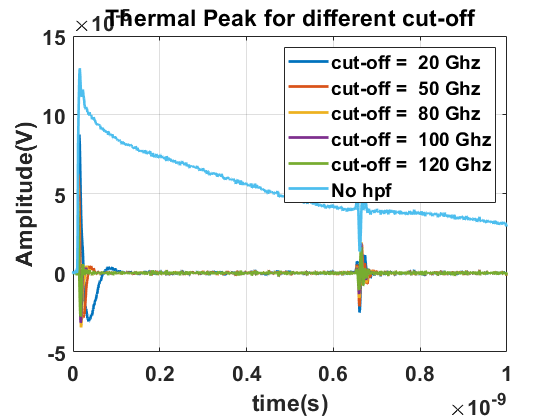

figure
for i=1:length(f_end)
    plot(hpf_thermal_peak{i}(:,1),hpf_thermal_peak{i}(:,2),"LineWidth",2);
    legend_str(i) = strjoin(["cut-off = " num2str(f_end(i)) "Ghz"]);
    xlabel("time(s)")
    ylabel("Amplitude(V)")
    hold on
end
legend_str(i+1) = "No hpf";
plot(thermdecay_noFZP_s6_newconfigpd2_366mV(:,1),thermdecay_noFZP_s6_newconfigpd2_366mV(:,2),"LineWidth",2)
legend(legend_str)
title("Thermal Peak for different cut-off")
set(gca,'FontSize',16,'FontWeight','bold')
grid on

## Plotting multiple echoes for old and new configuration

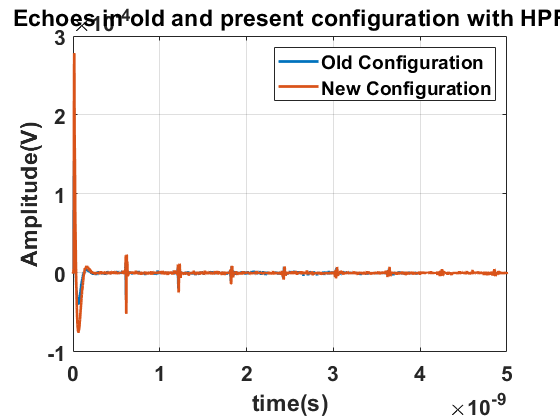

figure
plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echoes in old and present configuration with HPF")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

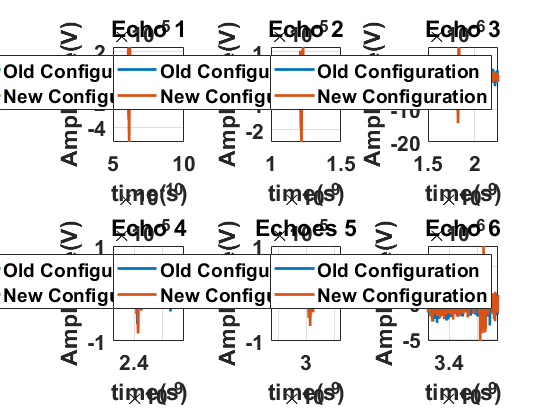

figure
subplot (2,3,1)
plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echo 1")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([0.5e-9,1e-9])

subplot (2,3,2)
plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echo 2")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([1e-9,1.5e-9])

subplot (2,3,3)
plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echo 3")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([1.5e-9,2.25e-9])
subplot(2,3,4)

plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echo 4")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([2.25e-9,2.75e-9])

subplot (2,3,5)
plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echoes 5")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([2.75e-9,3.25e-9])

subplot (2,3,6)
plot(multechos_FZP_s2_1y19x_filt(:,1),multechos_FZP_s2_1y19x_filt(:,2),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Echo 6")
legend(["Old Configuration" "New Configuration"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([3.25e-9,3.75e-9])

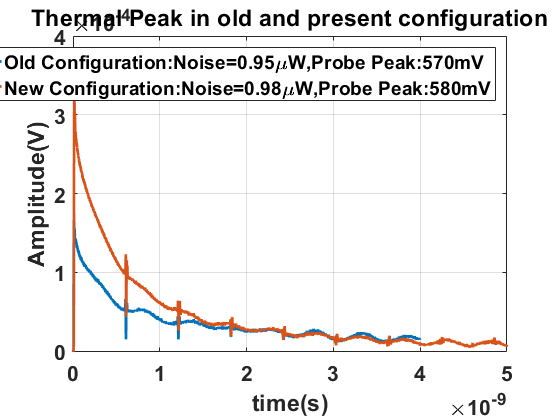



figure
plot(multechos_FZP_s2_1y19x(:,1),multechos_FZP_s2_1y19x(:,2),...
    multechos_noFZP_s2_newconfig(:,1),multechos_noFZP_s2_newconfig(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Thermal Peak in old and present configuration")
legend(["Old Configuration:Noise=0.95\muW,Probe Peak:570mV" "New Configuration:Noise=0.98\muW,Probe Peak:580mV"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

% xlim([0 0.4e-10])

## Comparison with the old and new photodetector

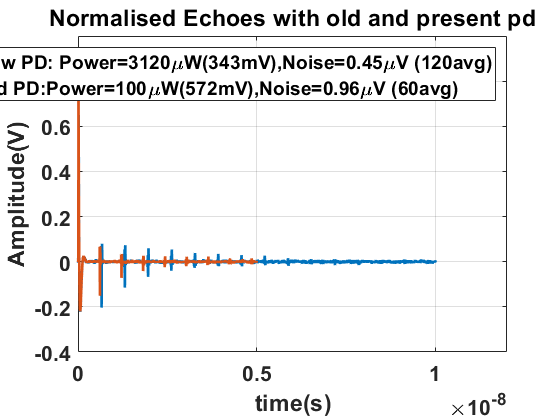


figure
plot(multecho_noFZP_s6_newconfigpd2_filt_343mV(:,1),multecho_noFZP_s6_newconfigpd2_filt_343mV(:,2)./max(multecho_noFZP_s6_newconfigpd2_343mV(:,2)),...
    multechos_noFZP_s2_newconfig_filt(:,1),multechos_noFZP_s2_newconfig_filt(:,2)./max(multechos_noFZP_s2_newconfig(:,2)),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Normalised Echoes with old and present pd")
legend(["New PD: Power=3120\muW(343mV),Noise=0.45\muV (120avg)"...
    "Old PD:Power=100\muW(572mV),Noise=0.96\muV (60avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

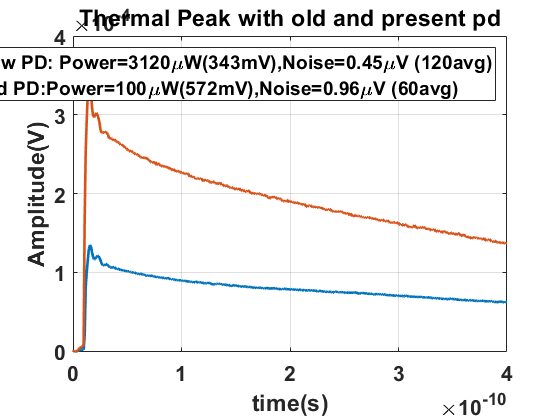


figure
plot(multecho_noFZP_s6_newconfigpd2_343mV(:,1),multecho_noFZP_s6_newconfigpd2_343mV(:,2),...
    multechos_noFZP_s2_newconfig(:,1),multechos_noFZP_s2_newconfig(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Thermal Peak with old and present pd")
legend(["New PD: Power=3120\muW(343mV),Noise=0.45\muV (120avg)"...
    "Old PD:Power=100\muW(572mV),Noise=0.96\muV (60avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([0 0.4e-9])

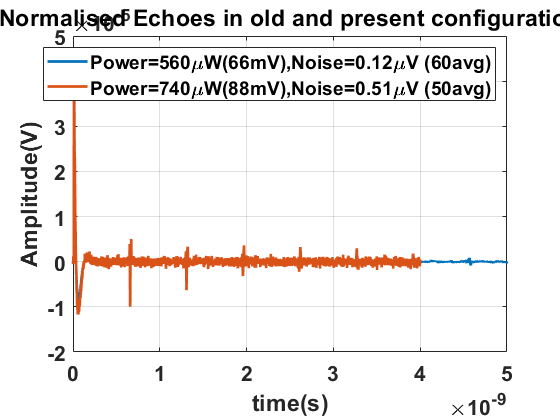


figure
plot(multechos_noFZP_s2_newconfigpd2_filt_66mV(:,1),multechos_noFZP_s2_newconfigpd2_filt_66mV(:,2),...
   multechos_noFZP_s2_newconfigpd2_filt_88mV(:,1),multechos_noFZP_s2_newconfigpd2_filt_88mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Normalised Echoes in old and present configuration")
legend(["Power=560\muW(66mV),Noise=0.12\muV (60avg)"...
    "Power=740\muW(88mV),Noise=0.51\muV (50avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

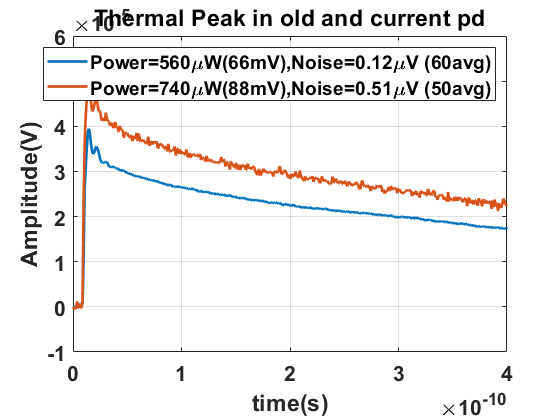


figure
plot(multechos_noFZP_s2_newconfigpd2_66mV(:,1),multechos_noFZP_s2_newconfigpd2_66mV(:,2),...
   multechos_noFZP_s2_newconfigpd2_88mV(:,1),multechos_noFZP_s2_newconfigpd2_88mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Thermal Peak in old and current pd")
legend(["Power=560\muW(66mV),Noise=0.12\muV (60avg)"...
    "Power=740\muW(88mV),Noise=0.51\muV (50avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([0 0.4e-9])

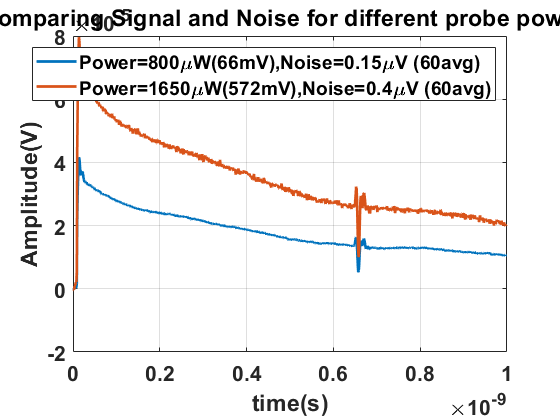

figure
plot(echo_noFZP_s2_newconfigpd2_96mV(:,1),echo_noFZP_s2_newconfigpd2_96mV(:,2),...
    echo_noFZP_s2_newconfigpd2_184mV(:,1),echo_noFZP_s2_newconfigpd2_184mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Comparing Signal and Noise for different probe powers")
legend(["Power=800\muW(66mV),Noise=0.15\muV (60avg)"...
    "Power=1650\muW(572mV),Noise=0.4\muV (60avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

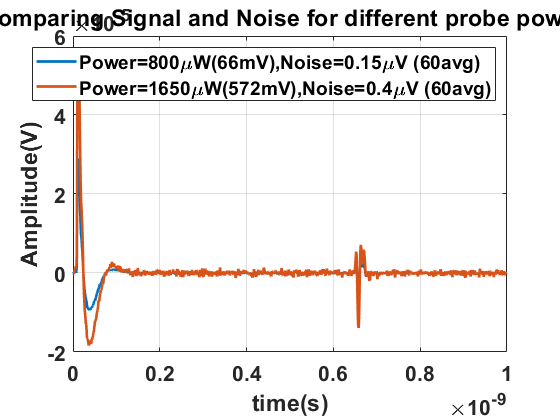

figure
plot(echo_noFZP_s2_newconfigpd2_filt_96mV(:,1),echo_noFZP_s2_newconfigpd2_filt_96mV(:,2),...
    echo_noFZP_s2_newconfigpd2_filt_184mV(:,1),echo_noFZP_s2_newconfigpd2_filt_184mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Comparing Signal and Noise for different probe powers")
legend(["Power=800\muW(66mV),Noise=0.15\muV (60avg)"...
    "Power=1650\muW(572mV),Noise=0.4\muV (60avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

## Comparing thermal peak and echoes with diffrent probe powers

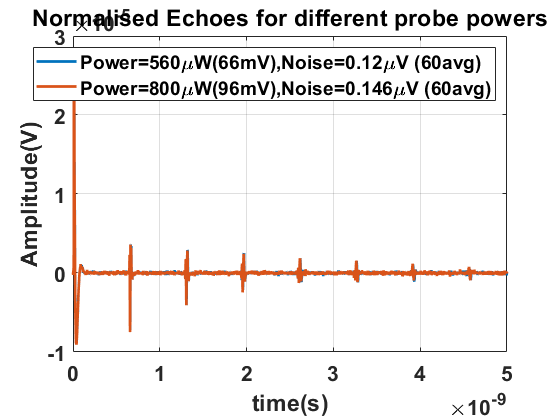

figure
plot(multechos_noFZP_s2_newconfigpd2_filt_66mV(:,1),multechos_noFZP_s2_newconfigpd2_filt_66mV(:,2),...
   multechos_noFZP_s2_newconfigpd2_filt_96mV(:,1),multechos_noFZP_s2_newconfigpd2_filt_96mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Normalised Echoes for different probe powers")
legend(["Power=560\muW(66mV),Noise=0.12\muV (60avg)"...
    "Power=800\muW(96mV),Noise=0.146\muV (60avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

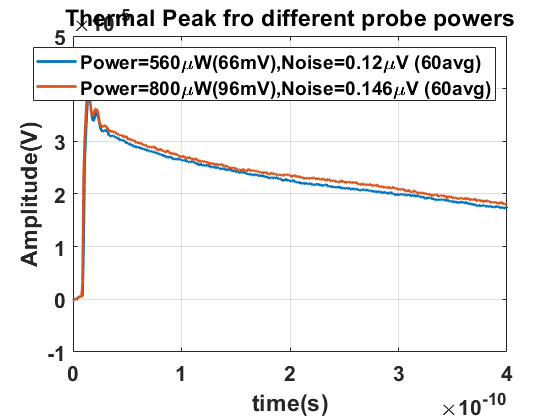


figure
plot(multechos_noFZP_s2_newconfigpd2_66mV(:,1),multechos_noFZP_s2_newconfigpd2_66mV(:,2),...
   multechos_noFZP_s2_newconfigpd2_96mV(:,1),multechos_noFZP_s2_newconfigpd2_96mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Thermal Peak fro different probe powers")
legend(["Power=560\muW(66mV),Noise=0.12\muV (60avg)"...
    "Power=800\muW(96mV),Noise=0.146\muV (60avg)" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
xlim([0 0.4e-9])

## Plotting signals with varying probe power

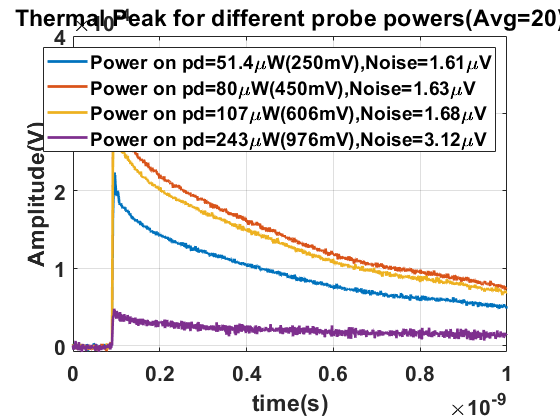

figure
plot(nofzp_new_config_s5_250mV(:,1),nofzp_new_config_s5_250mV(:,2),...
    nofzp_new_config_s5_450mV(:,1),nofzp_new_config_s5_450mV(:,2),...
    nofzp_new_config_s5_606mV(:,1),nofzp_new_config_s5_606mV(:,2),...
    nofzp_new_config_s5_976mV(:,1),nofzp_new_config_s5_976mV(:,2),'Linewidth',2)

xlabel("time(s)")
ylabel("Amplitude(V)")
title("Thermal Peak for different probe powers(Avg=20)")
legend(["Power on pd=51.4\muW(250mV),Noise=1.61\muV" "Power on pd=80\muW(450mV),Noise=1.63\muV"...
    "Power on pd=107\muW(606mV),Noise=1.68\muV" "Power on pd=243\muW(976mV),Noise=3.12\muV"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

## Comparing echoes at different cut-offs

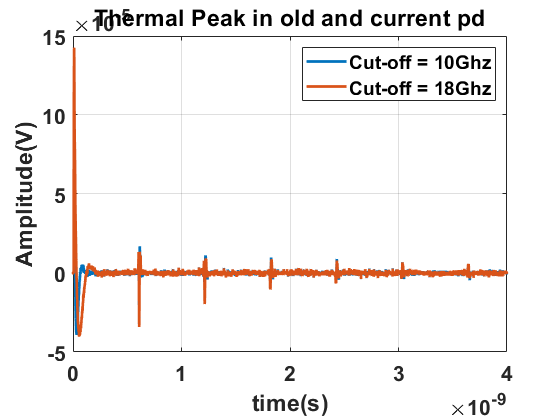

%multechos_FZP_s2_1y19x_filt_10Ghz = multechos_FZP_s2_1y19x_filt; % comment when cut-off set to 20Ghz
multechos_FZP_s2_1y19x_filt_20Ghz = multechos_FZP_s2_1y19x_filt; % comment when cut-off set to 10Ghz

figure
plot(multechos_FZP_s2_1y19x_filt_10Ghz(:,1),multechos_FZP_s2_1y19x_filt_10Ghz(:,2),...
   multechos_FZP_s2_1y19x_filt_20Ghz(:,1),multechos_FZP_s2_1y19x_filt_20Ghz(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Thermal Peak in old and current pd")
legend(["Cut-off = 10Ghz"...
    "Cut-off = 18Ghz" ])
set(gca,'FontSize',16,'FontWeight','bold')
grid on

% xlim([0 0.4e-9])

## Plotting 10 echoes at different probe powers

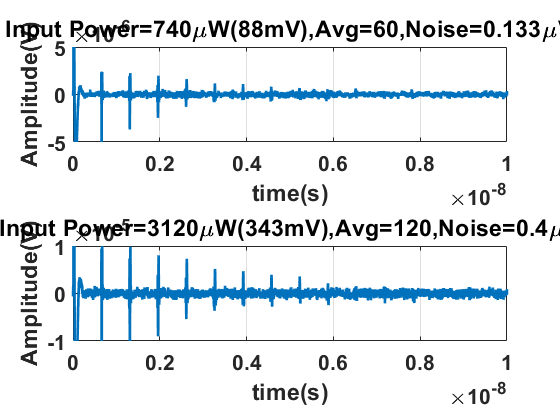

figure
subplot(2,1,1)
plot(multecho_noFZP_s6_newconfigpd2_filt_88mV(:,1),multecho_noFZP_s6_newconfigpd2_filt_88mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Input Power=740\muW(88mV),Avg=60,Noise=0.133\muV")
set(gca,'FontSize',16,'FontWeight','bold')
grid on
ylim([-5e-6 5e-6])
xlim([0 1e-8])
    
subplot(2,1,2)
plot(multecho_noFZP_s6_newconfigpd2_filt_343mV(:,1),multecho_noFZP_s6_newconfigpd2_filt_343mV(:,2),"LineWidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("Input Power=3120\muW(343mV),Avg=120,Noise=0.4\muV")
set(gca,'FontSize',16,'FontWeight','bold')
grid on
ylim([-10e-6 10e-6])
xlim([0 1e-8])

## Measuring Signal at the tip

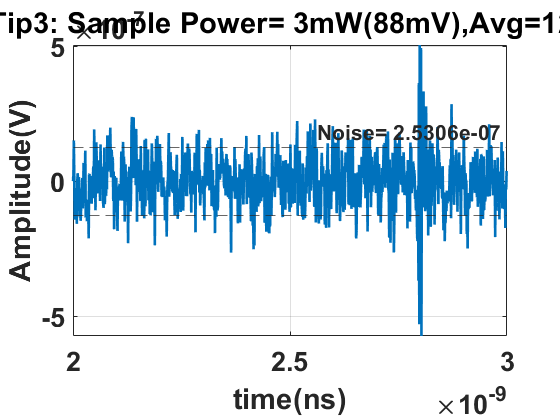

error_avg_60 = err_avg120_1*sqrt(2); 
figure

plot(tip_newpd_s3_3_filt(:,1),tip_newpd_s3_3_filt(:,2),"LineWidth",2)
yline(error_avg_60,'--',strjoin(["Noise=" num2str(2*error_avg_60)]),"Fontsize",16,"FontWeight",'bold')
yline(-error_avg_60,'--')
xlabel("time(ns)")
ylabel("Amplitude(V)")
title("Tip3: Sample Power= 3mW(88mV),Avg=120")
set(gca,'FontSize',20,'FontWeight','bold')
grid on

% ylim([-5e-6 5e-6])
 %xlim([2.5 3])

## Testing Reflectometry due to bad adhesion

clear thermal_peak_window
del_t = 2.25e-11-1.56e-11;
frequency = 140e9;
%thermdecay_wo_disturbance = thermdecay_noFZP_s6_newconfigpd2_366mV(:,2)-...
 %   thermdecay_pumpoff_noFZP_s6_newconfigpd2_366mV(:,2);
 window_size = hpf_thermal_peak{5}(:,1)>2e-11 & hpf_thermal_peak{5}(:,1)<7e-11;
 thermal_peak_window = hpf_thermal_peak{5}(window_size,:)

thermal_peak_window = 	1.0e+-5 *

    0.0000   -0.4233
    0.0000    0.2550
    0.0000    0.5682
    0.0000    0.3735
    0.0000    0.1098
    0.0000    0.0949
    0.0000   -0.1291
    0.0000   -0.0601
    0.0000    0.0050
    0.0000    0.1012


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000005 



s = 	1.0e+11 *

    0.0000
   -2.6642
    0.0000
   -0.0000
    0.0000


nmrs = 4.7500e-06

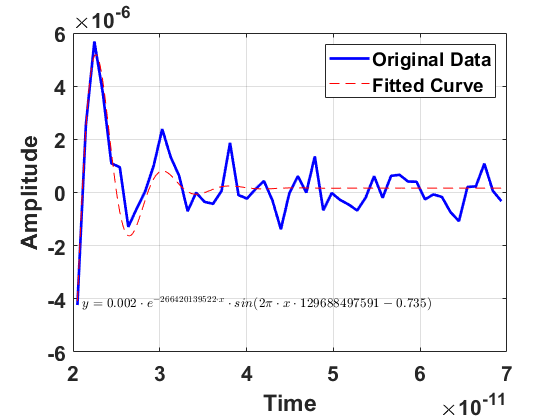

% [thermal_peak_window(:,1),~,thermal_peak_window(:,2)] = extract_window(hpf_thermal_peak{4}(:,1),...
%     hpf_thermal_peak{5}(:,2),del_t,0.4e-11); 

% modelfun = @(b,x)(b(1).*exp(b(2).*x) + b(3).*exp(b(4).*x)+ b(5).*exp(b(6).*x).*sin(2*pi*frequency.*x))
% beta0 = [1e-4 -1e-10 1e-4 -1e-10 1e-4 -1e-10]
% opts = statset('nlinfit');
% opts.RobustWgtFun = 'bisquare';
% f = nlinfit(thermal_peak_window(:,1),thermal_peak_window(:,2),modelfun,beta0,opts);

% f = fit(thermal_peak_window(:,1),thermal_peak_window(:,2),'exp2')
%time_constant = min(-1./[f.b f.d])
%reflectivity = exp(-1/(time_constant*frequency))


%fo = fitoptions('Method','NonlinearLeastSquares',...
%               'Lower',[0,0,0,0],...
%               'Upper',[1e-3,1e12,2*pi*200e9],...
%               'StartPoint',[1e-4,1e11,2*pi*frequency]);
%f = fittype('a*exp(-b*x)sin(c*x)'); 
%[fit1,gof,fitinfo] = fit(thermal_peak_window(:,1),thermal_peak_window(:,2),f,'options',fo);

[coefficients,number_of_iters] = fit_damped_sine(thermal_peak_window(:,1),thermal_peak_window(:,2),1e11);

    
% figure
% plot(thermdecay_noFZP_s6_newconfigpd2_366mV(:,1),...
%     thermdecay_wo_disturbance,"LineWidth",2)
% hold on
% plot(f)
% xlabel("Time(s)")
% ylabel("Ampltude(V)")
% title("Thermal peak without disturbance")
% legend(["Thermal Peak" "Fitted Exponential"])
% set(gca,'FontSize',16,'FontWeight','bold')
% hold off
% grid on    

## Extracting Echoes

% t_thermal_peak = [8.7899e-11 3.32065e-11 8.7899e-11 8.7899e-11 8.7899e-11];
first_echo_pump_shift = {full_noFZP_s2_1y1x_filt full_noFZP_s2_1y2x_filt full_noFZP_s2_1y3x_filt...
    full_noFZP_s2_1y4x_filt full_noFZP_s2_1y5x_filt full_noFZP_s2_1y6x_filt full_noFZP_s2_1y7x_filt};
[~,idx_after_peak] = min(abs(full_noFZP_s2_1y1x_filt(:,1)-4e-10));
% [~,idx_after_peak(2)] = min(abs(full_noFZP_s1_8y3x_filt(:,1)-t_thermal_peak(1)-2e-10));
% [~,idx_after_peak(3)] = min(abs(full_noFZP_s1_8y6x_filt(:,1)-t_thermal_peak(1)-2e-10));
% [~,idx_after_peak(4)] = min(abs(full_noFZP_s1_8y7x_filt_2(:,1)-t_thermal_peak(1)-2e-10));
% idx_after_peak = idx_after_peak(i)*ones(1,8)

## Plotting echoes with pump movement


figure
for a = 1:numel(first_echo_pump_shift)
    plot(first_echo_pump_shift{a}(idx_after_peak:end,1),...
        (a/4 + first_echo_pump_shift{a}(idx_after_peak:end,2)),"LineWidth",2)
    xlabel("time(s)")
    ylabel("Experiment number")
    title("First echo from the cantilever near the tip region")
    set(gca,'FontSize',16,'FontWeight','bold')
%     legend(["8y11x" "8y12x" "8y13x" "8y14x" "8y16x" "8y15x" "8y17x" "8y18x" "8y19x"])
    hold on
    grid on
end
legend([ "1y1x" "1y2x" "1y3x" "1y4x" "1y5x" "1y6x" "1y7x" "1y8x"])

## Adding similar signals of different average

full_noFZP_s1_filt = (full_noFZP_s1_1_filt*(N_avg1) + full_noFZP_s1_2_filt*(N_avg2))/(N_avg1 + N_avg2);


figure
plot(full_noFZP_s1_filt(:,1),full_noFZP_s1_filt(:,2))
ylabel("Amplitude(V)")
xlabel("time(s)")
% legend(["original signal" "highpass(8Ghz)"])
set(gca,'FontSize',16,'FontWeight','bold')
grid on
title(strjoin(["N_avg=" num2str(N_avg) ",Probe power =" num2str(Probe_peak)],''))
grid on

## Visualising signals over probe alignment

home_dir = 'D:/experiment_pics/';
plotflag = 1;
date = '05_2022/12_05_22';
sig_var_pump_x = readtable([home_dir '/' date '/' 'sig_var_pump_probe_tip_x.xlsx']);
sig_var_pump_x_dat = table2array(sig_var_pump_x(1:end,:));

figure
plot(sig_var_pump_x_dat(:,1),sig_var_pump_x_dat(:,3),...
    sig_var_pump_x_dat(:,1),sig_var_pump_x_dat(:,4),"LineWidth",2,"Marker","*")
legend(["Thermal peak" "First Echo"])
xlabel("Number of steps")
ylabel("Amplitude (V)")
title("Signal vs number of steps moved by the pump in x")
set(gca,'FontSize',14,'FontWeight','bold')
grid on
figure
plot(sig_var_pump_x_dat(:,1),sig_var_pump_x_dat(:,5),"LineWidth",2,"Marker","*")
% legend(["Thermal peak" "First Echo"])
xlabel("Number of steps")
ylabel("Time (s)")
title("Time of arrival vs number of steps moved by the pump in x")
grid on

sig_var_pump_probe_y = readtable([home_dir '/' date '/' 'sig_var_pump_probe_y.xlsx']);
sig_var_pump_probe_y_dat = table2array(sig_var_pump_probe_y);

figure
plot(sig_var_pump_probe_y_dat(:,1),sig_var_pump_probe_y_dat(:,3),...
    sig_var_pump_probe_y_dat(:,1),sig_var_pump_probe_y_dat(:,4),"LineWidth",2,"Marker","*")
legend(["Thermal peak" "First Echo"])
xlabel("Number of steps")
ylabel("Time(s)")
title("Signal variation vs number of steps moved by the pump in y")
grid on


## Visualising signals over pump alignment

home_dir = 'D:/experiment_pics';
date = '06_2022';
sig_var_pump_x = readtable([home_dir '/' date '/' 'aligning_tip_wrt_pump_x.xlsx']);

sig_var_pump_x_dat = table2array(sig_var_pump_x);
sig_var_pump_y = readtable([home_dir '/' date '/' 'aligning_tip_wrt_pump_y.xlsx']);

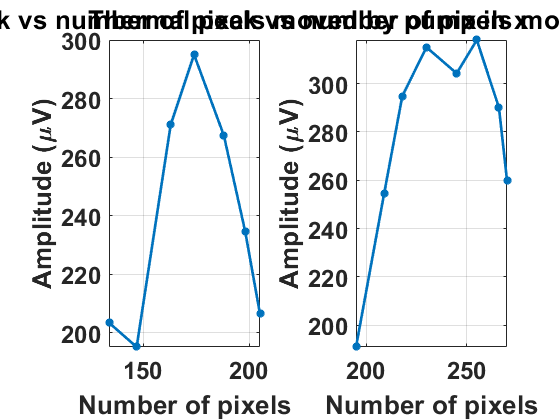

sig_var_pump_y_dat = table2array(sig_var_pump_y);


figure
% yyaxis left
% plot(sig_var_pump_x_dat(:,2),sig_var_pump_x_dat(:,3),"LineWidth",2,"Marker","*")
% xlabel("Number of pixels")
% ylabel("Probe Power (pump on) (mV)")
% title("Signal vs number of pixels moved by pump in x")
% set(gca,'FontSize',20,'FontWeight','bold')

% yyaxis right
subplot(1,2,1)
plot(sig_var_pump_x_dat(:,2),sig_var_pump_x_dat(:,4),"LineWidth",2,"Marker","*")
xlabel("Number of pixels")
ylabel("Amplitude (\muV)")
title("Thermal peak vs number of pixels moved by pump in x")
set(gca,'FontSize',18,'FontWeight','bold')
grid on

% yyaxis left
% plot(sig_var_pump_y_dat(:,2),sig_var_pump_y_dat(:,3),"LineWidth",2,"Marker","*")
% xlabel("Number of pixels")
% ylabel("Probe Power (pump on) (mV)")
% title("Signal vs number of pixels moved by pump in y")
% set(gca,'FontSize',20,'FontWeight','bold')
% 
% yyaxis right
subplot(1,2,2)
plot(sig_var_pump_y_dat(:,2),sig_var_pump_y_dat(:,4),"LineWidth",2,"Marker","*")
xlabel("Number of pixels")
ylabel("Amplitude (\muV)")
title("Thermal peak vs number of pixels moved by pump in y")
set(gca,'FontSize',18,'FontWeight','bold')
grid on

## Removing disturbance signal

### Step1. Plotting thermal peak without filtering

figure
plot(full_FZP_s2_pump_on_1y13x(:,1),full_FZP_s2_pump_on_1y13x(:,2),...
    full_FZP_s2_pump_off_1y13x(:,1),full_FZP_s2_pump_off_1y13x(:,2),"Linewidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("On FZP, Avg = 30, Probe power = 520mV")
grid on
legend(["Thermal Peak" "Disturbance Signal"])
set(gca,'FontSize',16,'FontWeight','bold')

figure
plot(full_noFZP_s2_pump_on_1y13x(:,1),full_noFZP_s2_pump_on_1y13x(:,2),...
    full_noFZP_s2_pump_off_1y13x(:,1),full_noFZP_s2_pump_off_1y13x(:,2),"Linewidth",2)
xlabel("time(s)")
ylabel("Amplitude(V)")
title("On Cantilever body, Avg = 30, Probe power = 520mV")
grid on
set(gca,'FontSize',16,'FontWeight','bold')
legend(["Thermal Peak" "Disturbance Signal"])

### **  Step 2. Removing disturbance**

full_FZP_wo_disturbance_norm = [full_FZP_s2_pump_on_1y13x(:,1),...
    (full_FZP_s2_pump_on_1y13x(:,2) - full_FZP_s2_pump_off_1y13x(:,2))./max(full_FZP_s2_pump_on_1y13x(:,2))];
full_noFZP_wo_disturbance_norm = [full_noFZP_s2_pump_on_1y13x(:,1),...
    (full_noFZP_s2_pump_on_1y13x(:,2) - full_noFZP_s2_pump_off_1y13x(:,2))./max(full_noFZP_s2_pump_on_1y13x(:,2))];

figure
plot(full_FZP_wo_disturbance_norm(:,1),full_FZP_wo_disturbance_norm(:,2),...
    full_noFZP_wo_disturbance_norm(:,1),full_noFZP_wo_disturbance_norm(:,2),"Linewidth",2)
xlabel("time(s)")
ylabel("Amplitude Norm")
title("Normalised Thermal Peak without disturbance signal, Avg = 30, Probe power = 520mV")
grid on
legend(["On FZP" "Off FZP"])
set(gca,'FontSize',16,'FontWeight','bold')

## Functions

function [f_sig, S_sig] = take_fft(home_dir,date,name,del_t,time_window_size)

    [~,~,first_echo_Sig] = extract_first_echo(home_dir,date,name,del_t,time_window_size,0); 
    
    first_echo_time_sig = first_echo_Sig(:,1);
    first_echo_sig = first_echo_Sig(:,2);
    
    pad_length = 4^nextpow2(length(first_echo_time_sig));
    
    f_sig = 0:1/(pad_length*(first_echo_time_sig(2)-first_echo_time_sig(1)))...
        :(1/(first_echo_time_sig(2)-first_echo_time_sig(1)))-1/(pad_length*(first_echo_time_sig(2)-first_echo_time_sig(1)));
        
    S_sig = fft(first_echo_sig,pad_length);
    
      

end

function [data,data_filt, echo_location,error] = extract_first_echo_selected_phase(home_dir,date,name,del_t,time_window_size,plotflag,N_avg,Probe_power,Sample_power,phase_selection,win) 
    file = load([home_dir '/' date '/' name '.mat']);
    % Extracting signal from the echo window
    signal_windows = file.Ym2;
    signal_windows_time = file.tbis;
    data(:,2) = signal_windows(:,1);data_Sig = data(:,2);
    data(:,1) = signal_windows_time(:,1);data_time = data(:,1);
    
    % Padding data with constant values to remove border effect
    zero_time_window = 0.2e-9;
    [t_zeros,t_zero_idx] = min(abs(data(:,1) - data(1,1) - zero_time_window));
    zero_added_data = [data(1,2)*ones(t_zero_idx,1); data(:,2)]; 
    
        % Filtering 2Ghz disturbance from the signal
    f_start = 1e9;
    f_end = 18e9;
    f_sampling = 1/(data(2,1)-data(1,1));
    data_filt(:,1) = data(:,1);
    
    band_stop_Filt = designfilt('bandstopiir','FilterOrder',2, ...
         'PassbandFrequency1',f_start,'PassbandFrequency2',f_end, ...
         'SampleRate',f_sampling);
    
    hpFilt = designfilt('highpassiir','FilterOrder',2, ...
         'PassbandFrequency',f_end,'PassbandRipple',0.2, ...
         'SampleRate',f_sampling);
%     fvtool(band_stop_Filt)
    
    %[data_filt(:,2)] = filter(band_stop_Filt,data(:,2));
    zero_added_data_filt = filter(hpFilt,zero_added_data);
    data_filt(:,2) = zero_added_data_filt(t_zero_idx+1:end);
    
    if plotflag == 1
%         figure
%         plot(signal_windows_time(:,1),signal_windows(:,1),"LineWidth",2)
%         hold on
% %         plot(data_filt(:,1),data_filt(:,2))
%         ylabel("Amplitude(V)")
%         xlabel("time(s)")
% %         legend(["original signal" "highpass(8Ghz)"])
%         set(gca,'FontSize',16,'FontWeight','bold')
%         title(strjoin(["Window 1: Avg=" num2str(N_avg) ",Probe power =" num2str(Probe_power)],''))
%         grid on
        
        figure
        plot(data(:,1),data(:,2),"LineWidth",2)
        hold on
        plot(data_filt(:,1),data_filt(:,2),"LineWidth",2)
        ylabel("Amplitude(V)")
        xlabel("time(s)")
        legend(["original signal" strjoin(["highpass(" num2str(f_end/1e9) "Ghz)"])])
        set(gca,'FontSize',16,'FontWeight','bold')
        title(strjoin(["Window " num2str(win) ":Avg=" num2str(N_avg) ",Probe peak =" num2str(Probe_power) "Power on Sample = " num2str(Sample_power)],''))
        grid on
        
        
    end
    
    echo_location(2,:) = data_filt(:,2)-mean(data_filt(:,2)); 
    
    % Calculate noise if thermal peak and any other signal is available, otherwise calculate noise from the
    % entire window if no signal is available
    if phase_selection== 0
         [noise_window, error] = standard_error_win1(data_filt(:,1),data_filt(:,2),del_t,time_window_size);
    else
        error = std(data_filt(data_filt(:,1)<time_window_size(1) | data_filt(:,1)>time_window_size(2),2));
    end
   
end

function [data,data_filt, first_echo_sig,error] = extract_first_echo(home_dir,date,name,del_t,time_window_size,plotflag,N_avg,Probe_power,norm,pos_name,phase_selection) 
    file = load([home_dir '/' date '/' name '.mat']);
    
    % Data extraction from selected window if phase selection is turned on    
    if phase_selection == 0 
        
        data(:,2) = file.Sig;data_Sig1 = data(:,2);
        
        data(:,1) = file.treal;data_time = data(:,1);
        
    else
        
        data_Sig1 = file.Ym2; data(:,2) = cat(2,data_Sig1);
        
        time = file.tbis;
        data(:,1) = cat(2,time);data_time = data(:,1);
        
    end
    
    % Normalising the data with the thermal peak
    if norm == 1
        data_norm(:,2) = data(:,2)/(max(data(:,2)));
        data_norm(:,1) = data(:,1);
        
    else 
        data_norm = data;
    end
    
    % Filtering 2Ghz disturbance from the signal
    f_start = 1e9;
    f_end = 120e9;
    f_sampling = 1/(data(2,1)-data(1,1));
  
    data_filt(:,1) = data(:,1);
    
    band_stop_Filt = designfilt('bandstopiir','FilterOrder',2, ...
         'PassbandFrequency1',f_start,'PassbandFrequency2',f_end, ...
         'SampleRate',f_sampling);
    
    hpFilt = designfilt('highpassiir','FilterOrder',2, ...
         'PassbandFrequency',f_end,'PassbandRipple',0.2, ...
         'SampleRate',f_sampling);
%     fvtool(band_stop_Filt)
    
    %[data_filt(:,2)] = filter(band_stop_Filt,data(:,2));
    [data_filt(:,2)] = filter(hpFilt,data(:,2));
    
    % Normalising the filtered data with the thermal peak
    if norm == 1
        data_filt(:,2) = data_filt(:,2)/(max(data(:,2)));
    end
   
    if plotflag == 1
        figure
        plot(data_norm(:,1),data_norm(:,2),"LineWidth",2)
        hold on
        plot(data_filt(:,1),data_filt(:,2),"LineWidth",2)
        ylabel("Amplitude(V)")
        xlabel("time(s)")
        legend(["original signal" strjoin(["highpass(" num2str(f_end/1e9) "Ghz)"])])
        set(gca,'FontSize',16,'FontWeight','bold')
        title(strjoin([pos_name "Avg=" num2str(N_avg) ",Probe peak =" num2str(Probe_power),"mV"],''))
        grid on
    end
    
%     [data_filt(:,2),dig_filt] = bandstop(data(:,2),[f_start f_end], f_sampling);
    
    [th_peak,ind] = max(data_filt(:,2));
    
    [t_echo,t_echo_idx] = min(abs(data_time - (data_time(ind) + del_t)));    
    [t_echo_start,t_echo_start_idx] = min(abs(data_time - (data_time(ind) + del_t-(time_window_size/2))));
    [t_echo_end,t_echo_end_idx] = min(abs(data_time - (data_time(ind) + del_t+(time_window_size/2))));
    
    first_echo_sig(2,:) = data_filt(t_echo_start_idx:t_echo_end_idx,2);
    
    first_echo_sig(1,:) = data_filt(t_echo_start_idx:t_echo_end_idx,1);
    
    first_echo_sig(2,:) = first_echo_sig(2,:)-mean(first_echo_sig(2,:)); 
    
    % Calculate noise if thermal peak and any other signal is available, otherwise calculate noise from the
    % entire window if no signal is available
    if phase_selection== 0
         [noise_window, error] = standard_error_win1(data_filt(:,1),data_filt(:,2),del_t,time_window_size);
    else
        error = std(data_filt(:,2));
    end
end

function [data,data_filt, first_echo_sig,error] = average_signals(home_dir,date,name1,name2,...
    del_t,time_window_size,plotflag,N_avg1,N_avg2,Probe_power,norm,pos_name,phase_selection) % specify if the window is selected from phase (1) or by default

    file1 = load([home_dir '/' date '/' name1 '.mat']);
    file2 = load([home_dir '/' date '/' name2 '.mat']);
    
    % Data extraction from selected window if phase selection is turned on    
    if phase_selection == 0 
        
        data1(:,2) = file1.Sig;data_Sig1 = data1(:,2);
        data2(:,2) = file2.Sig;data_Sig2 = data2(:,2);
        
        data(:,2) = ((N_avg1*data1(:,2))+(N_avg2*data2(:,2)))/(N_avg1+N_avg2);data_Sig = data(:,2);
        data(:,1) = file1.treal;data_time = data(:,1);
        
    else
        
        data_Sig1 = file1.Ym2; data1(:,2) = cat(2,data_Sig1);
        data_Sig2 = file2.Ym2; data2(:,2) = cat(2,data_Sig2);
        
        data(:,2) = ((N_avg1*data1(:,2))+(N_avg2*data2(:,2)))/(N_avg1+N_avg2);data_Sig = data(:,2);
        time = file1.tbis;
        data(:,1) = cat(2,time);data_time = data(:,1);
        
    end
    
    
    
    % Normalising the data with the thermal peak
    if norm == 1
        data(:,2) = data(:,2)/(max(data(:,2)));
    end
    
    % Filtering 2Ghz disturbance from the signal
    f_start = 1e9;
    f_end = 18e9;
    f_sampling = 1/(data(2,1)-data(1,1));
    data_filt(:,1) = data(:,1);
    
    band_stop_Filt = designfilt('bandstopiir','FilterOrder',2, ...
         'PassbandFrequency1',f_start,'PassbandFrequency2',f_end, ...
         'SampleRate',f_sampling);
    
    hpFilt = designfilt('highpassiir','FilterOrder',2, ...
         'PassbandFrequency',f_end,'PassbandRipple',0.2, ...
         'SampleRate',f_sampling);
%     fvtool(band_stop_Filt)
    
    %[data_filt(:,2)] = filter(band_stop_Filt,data(:,2));
    [data_filt(:,2)] = filter(hpFilt,data(:,2));
   
    if plotflag == 1
        figure
        plot(data(:,1),data(:,2),"LineWidth",2)
        hold on
        plot(data_filt(:,1),data_filt(:,2),"LineWidth",2)
        ylabel("Amplitude(V)")
        xlabel("time(s)")
        legend(["original signal" strjoin(["highpass(" num2str(f_end) "Ghz)"])])
        set(gca,'FontSize',16,'FontWeight','bold')
        title(strjoin([pos_name "2cycleAvg=" num2str(N_avg1+N_avg2) ",Probe peak =" num2str(Probe_power) "mV"],''))
        grid on
    end
    
%     [data_filt(:,2),dig_filt] = bandstop(data(:,2),[f_start f_end], f_sampling);
    
    [th_peak,ind] = max(data_filt(:,2));
    
    [t_echo,t_echo_idx] = min(abs(data_time - (data_time(ind) + del_t)));    
    [t_echo_start,t_echo_start_idx] = min(abs(data_time - (data_time(ind) + del_t-(time_window_size/2))));
    [t_echo_end,t_echo_end_idx] = min(abs(data_time - (data_time(ind) + del_t+(time_window_size/2))));
    
    first_echo_sig(2,:) = data_filt(t_echo_start_idx:t_echo_end_idx,2);
    
    first_echo_sig(1,:) = data_filt(t_echo_start_idx:t_echo_end_idx,1);
    
    first_echo_sig(2,:) = first_echo_sig(2,:)-mean(first_echo_sig(2,:)); 
    
    % Calculate noise if thermal peak and any other signal is available, otherwise calculate noise from the
    % entire window if no signal is available
    if phase_selection== 0
         [noise_window, error] = standard_error_win1(data_filt(:,1),data_filt(:,2),del_t,time_window_size);
    else
        error = std(data_filt(:,2));
    end
end

function [noise_window, se] = standard_error_win1(data_time,data,first_echo_time,first_echo_width)%,del_t,time_window_size)  
%     first_echo_width = 0.5e-10;
%     first_echo_time = 0.5985e-9;
    second_echo_time = 2*first_echo_time;
    third_echo_time = 3*first_echo_time;
    del_t = (first_echo_time+second_echo_time)/2;
    time_window_size = (second_echo_time-first_echo_time)-first_echo_width;
    
    [noise_window(1,:),noise_window(2,:)] = extract_window(data_time,data,del_t,time_window_size);
    
    se = std(noise_window(2,:));%*size(first_echo_sig,2);
%     se = max(noise_window(2,:)) - min(noise_window(2,:));
    
    
end

function [first_echo_time_sig,first_echo_sig_zero_mean,first_echo_sig] = extract_window(data_time,data,del_t,time_window_size) 
%     file = load([home_dir '/' date '/' name '.mat']);
%     data = file.Sig;
%     data_time = file.treal;
    
    [th_peak,ind] = max(data);
    
    [t_echo,t_echo_idx] = min(abs(data_time - (data_time(ind) + del_t)));    
    [t_echo_start,t_echo_start_idx] = min(abs(data_time - (data_time(ind) + del_t-(time_window_size/2))));
    [t_echo_end,t_echo_end_idx] = min(abs(data_time - (data_time(ind) + del_t+(time_window_size/2))));
    
    first_echo_sig = data(t_echo_start_idx:t_echo_end_idx);
    
    first_echo_time_sig = data_time(t_echo_start_idx:t_echo_end_idx);
    
    first_echo_sig_zero_mean = first_echo_sig-mean(first_echo_sig); 
end

function [s,nmrs] = fit_damped_sine(x,y,b_initial)
    yu = max(y);
    yl = min(y);
    yr = (yu-yl);                                                                   % Range of ‘y’
    yz = y-yu+(yr/2);
    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                            % Returns Approximate Zero-Crossing Indices Of Argument Vector
    zt = x(zci(y));
    per = 2*mean(diff(zt));                                                         % Estimate period
    ym = mean(y);                                                                   % Estimate offset
    fit = @(b,x)  b(1) .* exp(b(2).*x) .* (sin(2*pi*x./b(3) + 2*pi/b(4))) + b(5);   % Objective Function to fit
    fcn = @(b) norm(fit(b,x) - y);                                                  % Least-Squares cost function
    [s,nmrs] = fminsearch(fcn, [yr; b_initial;  per;  -1;  ym])                           % Minimise Least-Squares
    xp = linspace(min(x),max(x), 500);
    figure
    plot(x,y,'b', 'LineWidth',2)
    hold on
    plot(xp,fit(s,xp), '--r')
    set(gca,'FontSize',16,'FontWeight','bold')
    hold off
    grid
    xlabel('Time')
    ylabel('Amplitude')
    legend('Original Data',  'Fitted Curve')
    text(0.3*max(xlim),0.7*min(ylim), sprintf('$y = %.3f\\cdot e^{%.0f\\cdot x}\\cdot sin(2\\pi\\cdot x\\cdot %.0f%.3f)$', [s(1:2); 1./s(3:4)]), 'Interpreter','latex')
end